# Laboratorium 5

# Modulacja Kwadraturowa

### ***ZAD1 SPRAWDZANIE ORTOGONALNOŚCI FUNKCJI***

Sprawdzenie ortogonalności funkcji: sinx, cosx, sin2x, cos2x, … , sin(x+pi/100), sin(x-pi/100) poprzez policzenie iloczynu skalarnego (+analitycznie) z podaniem wartości.

#### Podstawy matematyczne:

**Ortogonalność**  – uogólnienie pojęcia prostopadłości znanego z geometrii euklidesowej na abstrakcyjne przestrzenie z określonym iloczynem skalarnym, jak np. przestrzenie unitarne (w tym przestrzenie Hilberta) czy przestrzenie ortogonalne. Pojęcie ortogonalności bywa uogólnianie również na przestrzenie unormowane w których nie ma naturalnej struktury iloczynu skalarnego.

Aby sprawdzić czy dane wektory są ortogonalne, należy obliczyć ich iloczyn skalarny. Jeżeli iloczyn wyniesie 0, wektory są ortogonalne.

clc; clear; close all;

f = 1;
fs = f * 10;
dt = 1/fs;
t = 0:dt:2/f-1/fs;
x = 2*pi*f*t;

signal1 = sin(x);
signal2 = cos(x);
signal3 = sin(2*x);
signal4 = cos(2*x);
signal5 = sin(x+(pi/100));
signal6 = sin(x-(pi/100));


Wyznaczanie ortogonalności za pomocą funkcji:


ortogonalnosc_1 = dot(signal1, signal2)

ortogonalnosc_1 = 3.2196e-15

ortogonalnosc_2 = dot(signal3, signal4)

ortogonalnosc_2 = -3.8303e-15

ortogonalnosc_3 = dot(signal5, signal6)

ortogonalnosc_3 = 9.9803

Wyznaczanie ortogonalności za pomocą metody analitycznej - polega na tym, że próbkujemy sygnał co π/2, wówczas otrzymujemy wektory np.

sin(x) = [0, 1 , 0 ,-1, 0], cos(x) = [1 , 0, -1, 0, 1], następnie wyliczmy ich iloczyn skalarny i otrzymujemy wynik 0, świadczy to o tym, że są one ortogonalne

### Obserwacje i wnioski:

- Jeśli sygnały są takie same, a ich faza rożni się o 90 stopni, wówczas są ortogonalne.

- Gdy sygnały są ortogonalne funkcja zwraca wartości bliskie zeru, możemy je przybliżyć.

- Nawet niewielkie przesunięcie fazy sprawia, że funkcje już nie są ortogonalne.

## QAM **analogowo **i demodulacja QAM, sprawdzenie wpływu przesunięcia fazowego (symulacja opóźnienia kanału) 

#### Podstawy matematyczne:

Modulacja QAM polega na zakodowaniu sygnału w zmianach amplitud dwóch komponentów przesuniętych względem siebie o 90 stopni.

Matematycznie można przedstawić ją poniższym wzorem:

Funkcje simus oraz cosinus są wzgledem siebie ortogonalne (co wykazało poprzednie zadanie) zatem nie interferują. Skutkuje to powstaniem sygnału o zmodulowanej zarówno amplitudzie jak i fazie. 

Częstotliwość nośnej:

f = 100;
fs = f *100;

Przesunięcie fazowe nośnej sinus:

n = 0;

shift = ((2*pi)/360) * n;

Częstotliwość sygnału pierwszego:

f_s1 = 2;

Częstotliwość sygnału drugiego:

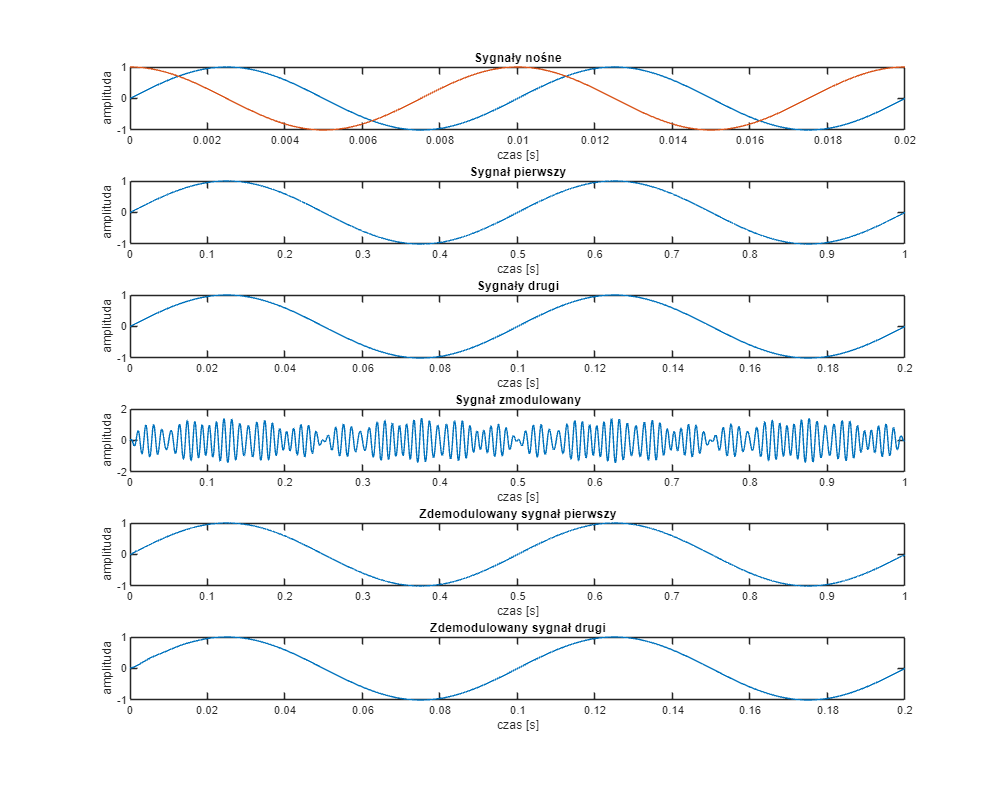

f_s2 = 10;

dt = 1/fs;
t = 0:dt:1-dt;
x = 2*pi*f*t;

%sygnały
n1 = sin(x + shift);
n2 = cos(x);

s1 = sin(2*pi*f_s1*t);
s2 = sin(2*pi*f_s2*t);

s_mod = s1.*n1 + s2.*n2;

%demodulacja
demod_s1 = 2*(lowpass(s_mod .* n1, f, fs, 'Steepness', 0.999));
demod_s2 = 2*(lowpass(s_mod .* n2, f, fs, 'Steepness', 0.999));

%wykresy
fig1 = figure;
fig1.Position = [0, 0, 1000, 800];

subplot(6,1,1)
plot(t, n1, t, n2)
xlim([0, 2/f])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnały nośne')

subplot(6,1,2)
plot(t, s1)
xlim([0, 2/f_s1])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał pierwszy')

subplot(6,1,3)
plot(t, s2)
xlim([0, 2/f_s2])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnały drugi')

subplot(6,1,4)
plot(t, s_mod)
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zmodulowany')

subplot(6,1,5)
plot(t, demod_s1)
xlim([0, 2/f_s1])
xlabel("czas [s]")
ylabel("amplituda")
title('Zdemodulowany sygnał pierwszy')

subplot(6,1,6)
plot(t, demod_s2)
xlim([0, 2/f_s2])
xlabel("czas [s]")
ylabel("amplituda")
title('Zdemodulowany sygnał drugi')

### Obserwacje i wnioski:

- Kiedy funkcje nośne nie są ortogonalne, pojawiają się problemy z demodulacją sygnałów(nachodzą one na siebie)

- Częstotliwość nośnej musi być conajmniej dwa razy większa od najwyższej częstotliwości przenoszonego sygnału.

- Kiedy funkcje są ortogonalne demodulacja przebiega poprawnie.

## **Cyfrowa modulacja 4QAM i 16QAM. Modulacja, demodulacja bezpośrednia, szumy.**

#### **Podstawy matematyczne:**

Schemat modulatora QAM

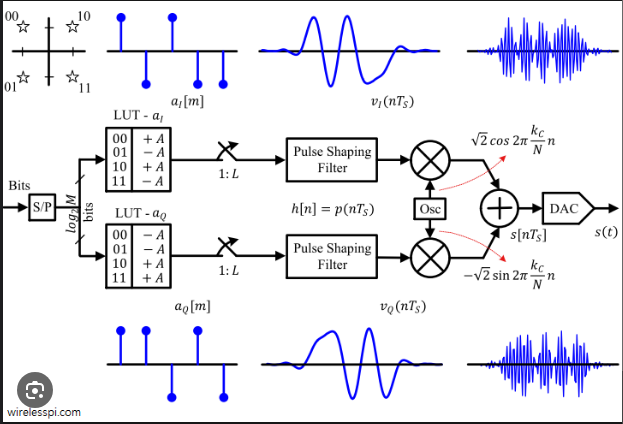

Cyfrowa modulacja QAM polega w pierwszej kolejności na zamianie sygnału cyfrowego na "symbole". Symbol jest sekwencją bitów która odpowiada jednej kombinacji amplitudy i fazy sygnału wyjściowego (jednemu punktowi na wykresie konstelacji). Każdy z symboli ma przypisaną wartość dla kanałów I (Inline) oraz Q (Quadrature) odpowiadającym odpowiednio komponentom amplitudy i fazy. Za tą część procesu odpowiada koder konstelacji. Jeżeli każdemu z symboli przypiszemy jedną kombinację bitów wejściowych, kodowanie to nazywamy kodowaniem bezpośrednim.

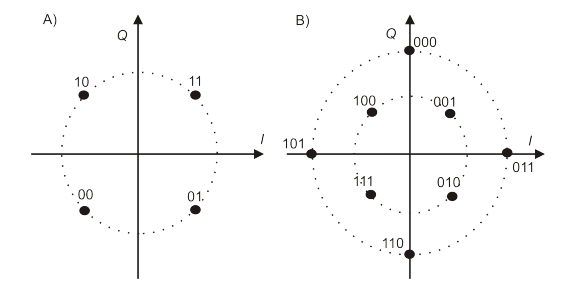Przykładowe konstelacje symboli modulacji z kodowaniem bezpośrednim.

Możemy zauważyć, że wzrost liczby bitów składających się na symbol nie przekłada się na zwiększenie pasma sygnału (wymaga jedynie większej liczby symboli) a jednak pozwala na przesłanie większej ilości informacji zwiększając przepustowość. Ceną którą za to płacimy jest pogorszenie odporności na szumy naszej transmisji. Zwiększenie ilości symboli powoduje zagęszczenie konstelacji a co za tym idzie zmniejszenie odstępów pomiędzy symbolami. Im mniejszy odstęp pomiędzy dwoma symbolami na wykresie konstelacji tym mniejsze zaburzenie fazy lub amplitudy może spowodować nałożenie się transmitowanego symbolu na inny symbol co poskutkuje błędem transmisji. Możemy temu przeciwdziałać zwiększając amplitude całego sygnału. Spowoduje to rozsunięcie symboli ale transmisja o większej amplitudzie wymaga nadajnika większej mocy.

Tego typu konstelacje narażone są na przekłamania w wyniku wystąpienia przesunięcia fazy. Jeżeli sygnał zostanie przesunięty o 90 stopni, konstelacja sygnału odbieranego będzie przekręcona o 90 stopni względem konstelacji sygnału nadawanego a odczytane symbole będą niezgodne z nadanymi. Uniemożliwić taką sytuację można stosując kodowanie różnicowe. Polega ono na zastosowaniu kodera zawierającego algorytm skutkujący powstaniem konstelacji o symetrycznym rozłożeniu symboli na wykresie konstelacji. W takim algorytmie informacje o słowie wejściowym kodowane są za pomocą przejść pomiędzy symbolami.

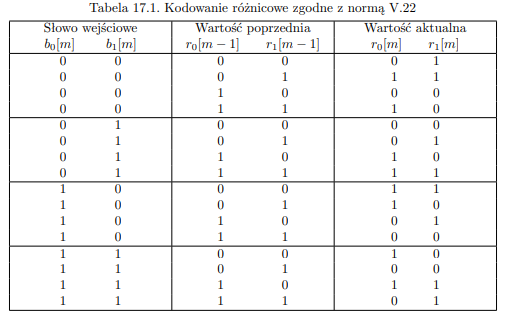przykładowa tablica kodowania różnicowego.

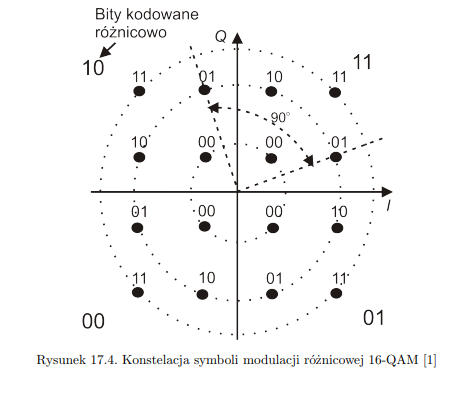przykładowa konstelacja symboli modulacji różnicowej.

Po zakodowaniu sygnał poddawany jest obróbce układem kształtującym. Ma on za zadanie dopasować sygnały inline i quadratic do wymaganego pasma częstotliwości.

Tak zakodowany sygnał zostaje zsumowany i przesłany do nadajnika.

Dekodowanie sygnału odbywa się poprzez wydobycie z odbieranego sygnału składowych Inline oraz Quadratic. Można to osiągnąć odpowiednio mnożąc odbierany sygnał przez funkcję cosinus dla Inline i sinus dla Quadratic. W wyniku otrzymujemy Odpowiednie sygnały z nałożonym sygnałem o wyższej czestotliwości który możemy odfiltrować dopasowanym filtrem dolnoprzepustowym. Tak obrobiony sygnał może zostać podany do dekodera wykonującego funkcję przeciwną do kodera zawartego w nadajniku.

**Symulacje:**

Poniżej zakodowano informację tekstową jako ciąg bitów, który następnie zakodowano zgodnie z tablicami dla konstelacji 4QAM i 16QAM oraz zwizualizowano kolejne sygnały widziane w nadajniku i odbiorniku.

clc; clear; close all;

input_message = reshape(dec2bin('Hello'),1, [])

input_message = '11111011110000010111011110000101001'

if (mod(length(input_message),2) == 1)
    input_message = [input_message, 0];
end

symbol_table = [[-1 -1]; [-1 1]; [1 -1]; [1 1]]

symbol_table =     -1    -1
    -1     1
     1    -1
     1     1


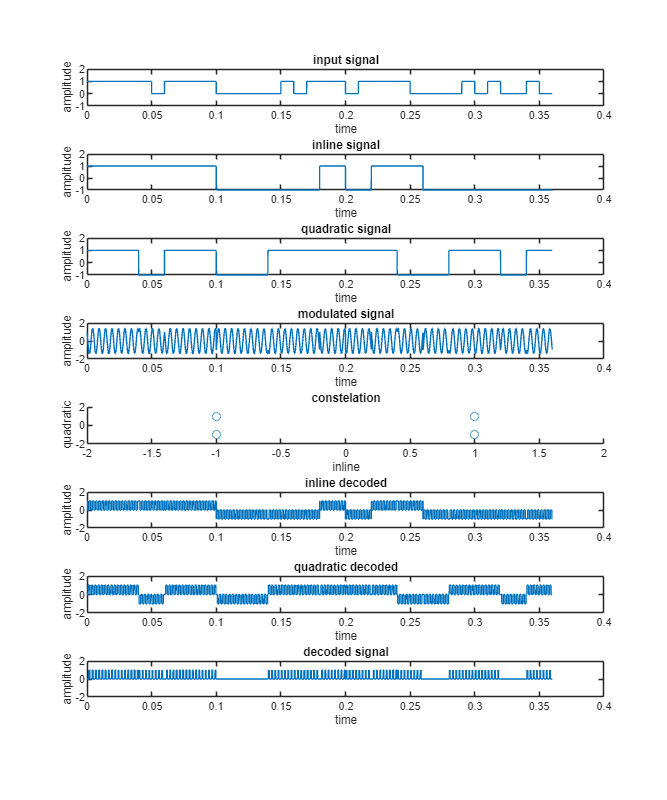


Inline = [];
Quadratic = [];
for i = 1:2:(length(input_message))-1
    Inline = [Inline, symbol_table(bin2dec(input_message([i, i+1]))+1,1)];
    Quadratic = [Quadratic, symbol_table(bin2dec(input_message([i, i+1]))+1,2)];
end

input_message = input_message=='1';

fc = 200;
Ts = 0.01;


fs = fc*100;
t = 0:1/fs:Ts*length(input_message)-1/fs;

input_signal = strech_sig(input_message, length(t)/length(input_message));
Inline = strech_sig(Inline, (length(t)/length(input_message))*2);
Quadratic = strech_sig(Quadratic, (length(t)/length(input_message))*2);


signal = Inline .* cos(2*pi*t*fc) - Quadratic .* sin(2*pi*t*fc);


decoded_Inline = round(signal .* cos(2*pi*fc*t));

decoded_Quadratic = -1 * round(signal .* sin(2*pi*fc*t));





decoded_signal = [];

for i = 1:2:length(decoded_Inline)
    if (decoded_Inline(i) > 0 && decoded_Quadratic(i) > 0)
        idx = '11';
    elseif (decoded_Inline(i) > 0 && decoded_Quadratic(i) < 0)
        idx = '10';
    elseif (decoded_Inline(i) < 0 && decoded_Quadratic(i) > 0)
        idx = '01';
    else
        idx = '00';
    end
    decoded_signal = [decoded_signal, idx];
end
decoded_signal = decoded_signal == '1';


rows = 8;
fig1 = figure;
fig1.Position = [0, 0, 1000, 1200];

subplot(rows, 1, 1)
plot(t, input_signal)
ylim([-1, 2])
title('input signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 2)
plot(t, Inline)
ylim([-1, 2])
title('inline signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 3)
plot(t, Quadratic)
ylim([-1, 2])
title('quadratic signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 4)
plot(t, signal)
ylim([-2, 2])
title('modulated signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 5)
scatter(Inline, Quadratic)
xlim([-2, 2])
ylim([-2, 2])
title('constelation')
xlabel('inline')
ylabel('quadratic')

subplot(rows, 1, 6)
plot(t, decoded_Inline)
%xlim([-2, 2])
ylim([-2, 2])
title('inline decoded')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 7)
plot(t, decoded_Quadratic)
%xlim([-2, 2])
ylim([-2, 2])
title('quadratic decoded')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 8)
plot(t, decoded_signal)
%xlim([-2, 2])
ylim([-2, 2])
title('decoded signal')
xlabel('time')
ylabel('amplitude')




input_message = reshape(dec2bin('hello world'),1, [])

input_message = '11111011111111111111110000001010010111001010011110110110000101110001001011000'

if (mod(length(input_message),4) ~= 0)
    input_message = [input_message, 0];
end

if (mod(length(input_message),4) ~= 0)
    input_message = [input_message, 0];
end

if (mod(length(input_message),4) ~= 0)
    input_message = [input_message, 0];
end

if (mod(length(input_message),4) ~= 0)
    input_message = [input_message, 0];
end

symbol_table = [[-3 -3]; [-3 -1]; [-3 3]; [-3 1]; [-1 -3]; [-1 -1]; [-1 3]; [-1 1]; [3 -3]; [3, -1]; [3 3]; [3 1]; [1, -3]; [1 -1]; [1, 3]; [1 1]]

symbol_table =     -3    -3
    -3    -1
    -3     3
    -3     1
    -1    -3
    -1    -1
    -1     3
    -1     1
     3    -3
     3    -1


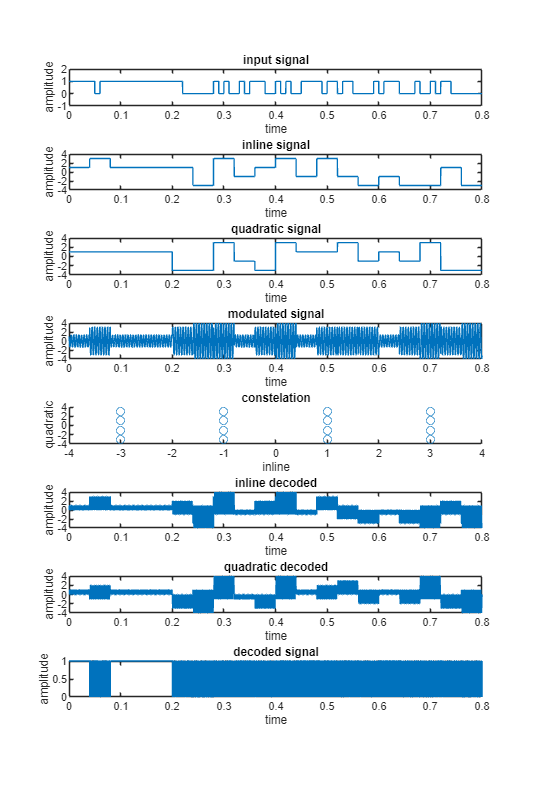


Inline = [];
Quadratic = [];
for i = 1:4:length(input_message)
    Inline = [Inline, symbol_table(bin2dec(input_message([i, i+1, i+2, i+3]))+1,1)];
    Quadratic = [Quadratic, symbol_table(bin2dec(input_message([i, i+1, i+2, i+3]))+1,2)];
end

input_message = input_message=='1';

fc = 200;
Ts = 0.01;


fs = fc*100;
t = 0:1/fs:Ts*length(input_message)-1/fs;

input_signal = strech_sig(input_message, length(t)/length(input_message));
Inline = strech_sig(Inline, (length(t)/length(input_message))*4);
Quadratic = strech_sig(Quadratic, (length(t)/length(input_message))*4);


signal = Inline .* cos(2*pi*t*fc) - Quadratic .* sin(2*pi*t*fc);


decoded_Inline = round(signal .* cos(2*pi*fc*t));

decoded_Quadratic = -1 * round(signal .* sin(2*pi*fc*t));


decoded_signal = [];

for i = 1:4:length(decoded_Inline)
    if (decoded_Inline(i) < -2 && decoded_Quadratic(i) < -2)
        idx = '0000';
    elseif (decoded_Inline(i) < -2 && decoded_Quadratic(i) < 0)
        idx = '0001';
    elseif (decoded_Inline(i) < -2 && decoded_Quadratic(i) > 2)
        idx = '0010';
    elseif (decoded_Inline(i) < -2 && decoded_Quadratic(i) > 0)
        idx = '0011';
    elseif (decoded_Inline(i) < 0 && decoded_Quadratic(i) < -2)
        idx = '0100';
    elseif (decoded_Inline(i) < 0 && decoded_Quadratic(i) < 0)
        idx = '0101';
    elseif (decoded_Inline(i) < 0 && decoded_Quadratic(i) > 2)
        idx = '0110';
    elseif (decoded_Inline(i) < 0 && decoded_Quadratic(i) > 0)
        idx = '0111';
    elseif (decoded_Inline(i) > 2 && decoded_Quadratic(i) < -2)
        idx = '1000';
    elseif (decoded_Inline(i) > 2 && decoded_Quadratic(i) < 0)
        idx = '1001';
    elseif (decoded_Inline(i) > 2 && decoded_Quadratic(i) > 2)
        idx = '1010';
    elseif (decoded_Inline(i) > 2 && decoded_Quadratic(i) > 0)
        idx = '1011';
    elseif (decoded_Inline(i) > 0 && decoded_Quadratic(i) < -2)
        idx = '1100';
    elseif (decoded_Inline(i) > 0 && decoded_Quadratic(i) < 0)
        idx = '1101';
    elseif (decoded_Inline(i) > 0 && decoded_Quadratic(i) > 2)
        idx = '1110';
    else
        idx = '1111';
    end
    decoded_signal = [decoded_signal, idx];
end
decoded_signal = decoded_signal == '1';


rows = 8;
fig1 = figure;
fig1.Position = [0, 0, 2000, 3000];

subplot(rows, 1, 1)
plot(t, input_signal)
ylim([-1, 2])
title('input signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 2)
plot(t, Inline)
ylim([-4, 4])
title('inline signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 3)
plot(t, Quadratic)
ylim([-4, 4])
title('quadratic signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 4)
plot(t, signal)
ylim([-4, 4])
title('modulated signal')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 5)
scatter(symbol_table(:,1), symbol_table(:,2))
xlim([-4, 4])
ylim([-4, 4])
title('constelation')
xlabel('inline')
ylabel('quadratic')

subplot(rows, 1, 6)
plot(t, decoded_Inline)
%xlim([-2, 2])
ylim([-4, 4])
title('inline decoded')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 7)
plot(t, decoded_Quadratic)
%xlim([-2, 2])
ylim([-4, 4])
title('quadratic decoded')
xlabel('time')
ylabel('amplitude')

subplot(rows, 1, 8)
plot(t, decoded_signal)
%xlim([-2, 2])
%ylim([-4, 4])
title('decoded signal')
xlabel('time')
ylabel('amplitude')

## Obserwacje:

Niestety nie udało się zdekodować przesłanej informacji ponieważ nie udało nam się dobrać odpowiedniego filtra pozwalającego uzyskac precyzyjne informacje z zdekodowanych komponentów kanału.

Obserwujemy jednak poprawnie przesłane obie składowe wizualnie odpowiadające komponentom nadanego sygnału, oraz poprawne wykresy konstelacji.

**Wnioski:**

Modulacja QAM zapewnia znacznie wiekszą przepustowość przy niedużym paśmie niż modulacja am czy fm. Jest jednak trudniejsza do zaimplementowania i wymaga większego skomplikowania układów nadawania i odbioru.

function out = strech_sig(sig, n)
    sig_out = [];
    for i = 1:length(sig)
        for j = 1:n
            sig_out = [sig_out, sig(i)];
        end
    end
    out = sig_out;
end